# import experimental data

file='/Users/madi/Documents/GitHub/MATLAB/MATLAB/Lab5/Lab5-2 Bode.txt';
fileID=fopen(file);
textstuff=textscan(fileID, '%s %s %s %s','Delimiter','\t');
fclose(fileID);

## organize experimental data

efreq=textstuff{1,1};
efreq=str2double(efreq);
efreq=efreq(4:27);
efreq=2.*pi.*efreq;

egain=textstuff{1,2};
egain=str2double(egain);
egain=egain(4:27);

ephase=textstuff{1,3};
ephase=str2double(ephase);
ephase=ephase(4:27);

## import CircuitLab data

clfile='/Users/madi/Documents/GitHub/MATLAB/MATLAB/Lab5/Lab 5 Pre-lab 1.csv';
cldata=readmatrix(clfile);

## organize circuitlab data

clfreq=cldata(:,1);
clfreq=2.*pi.*clfreq;

clgain=cldata(:,2);

clphase=cldata(:,3);

## plot

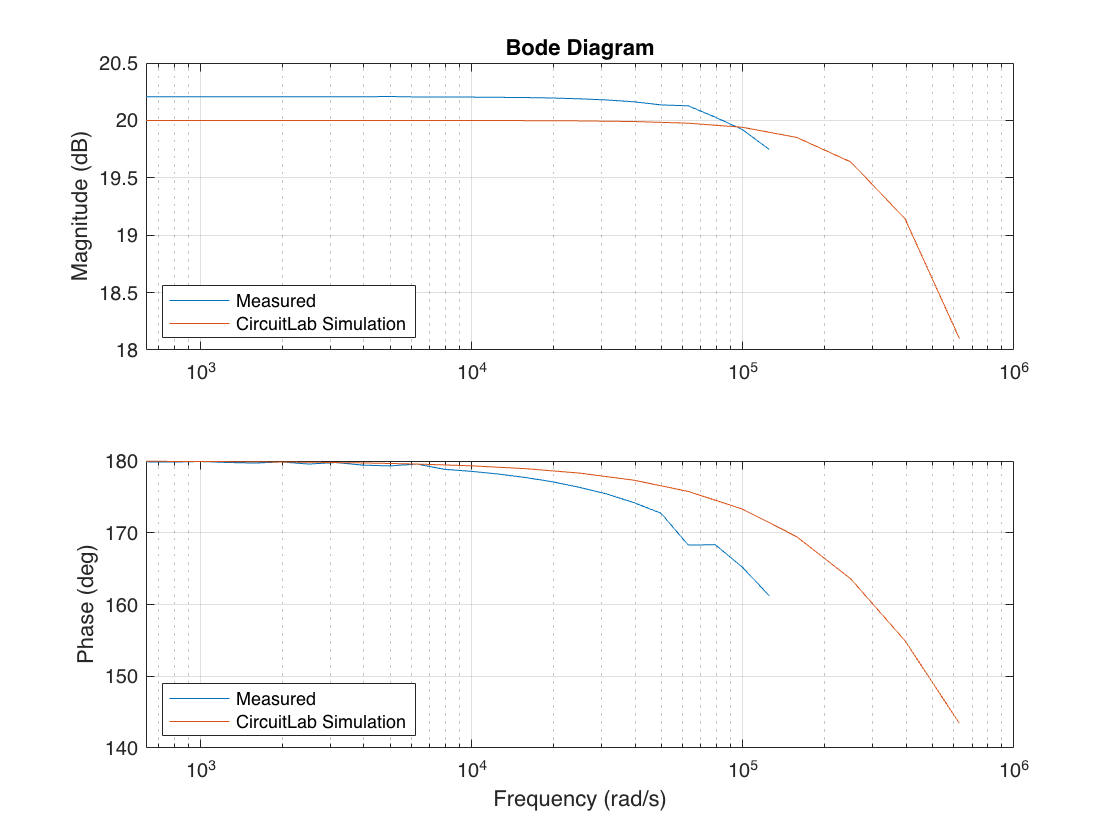

subplot(2,1,1);
semilogx(efreq,egain,'DisplayName','Measured');
hold on
semilogx(clfreq,clgain,'DisplayName','CircuitLab Simulation');
grid on
ylabel('Magnitude (dB)')
title('Bode Diagram')
legend('Location','southwest')

subplot(2,1,2);
semilogx(efreq,ephase,'DisplayName','Measured');
hold on 
semilogx(clfreq,clphase,'DisplayName','CircuitLab Simulation');
grid on
ylabel('Phase (deg)')
xlabel('Frequency (rad/s)')
legend('Location','southwest')
hold off